% Test For fourth sound

% Sound captured in school yard.
% Length :- 47 sec
% Reading the audio
[samples, fsample] = audioread('TestAudio4.wav');

player = audioplayer(samples, fsample);
play(player);


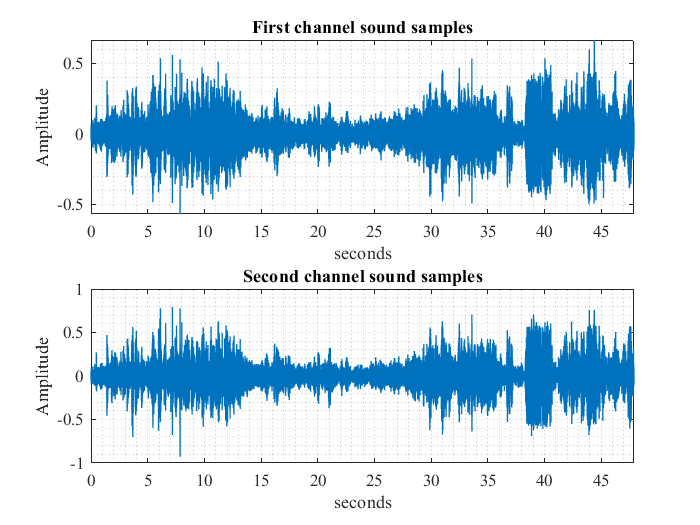

% Evidence handling and Initial assessment

% Waveform view
ShowWaveform(samples, fsample);

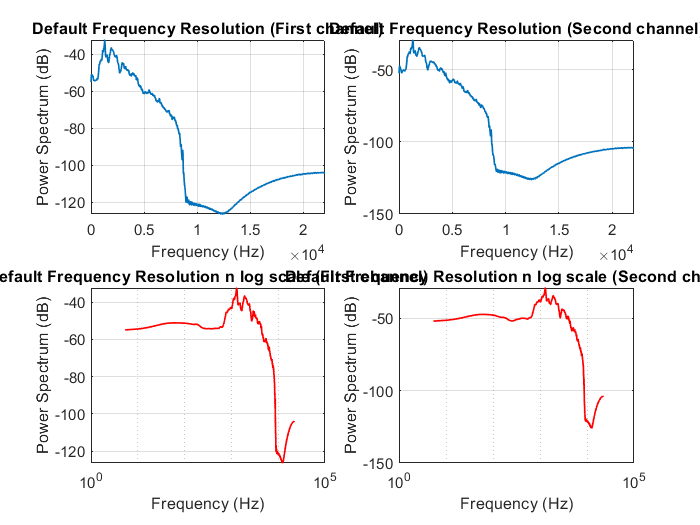


% PSD view
ShowPSD2(samples, fsample);


% Spectrogram view
% ShowSpectrogram(samples, fsample);
% Because it is too large size audio recording hence, spectrogram would
% take too much time

% Statistical view
audioStats(samples, fsample);

Max value in first Channel = 0.66412
Max value in second Channel = 0.79224
Minimum value in first Channel = -0.56741
Minimum value in second Channel = -0.92816
Mean value in first channel = -4.4066e-05
Mean value in second channel= -2.9928e-05
standard deviation of first channel= 0.073167
standard deviation of second channel= 0.099435
Variance of first channel= 0.0053534
Variance of second channel= 0.0098873
Power in first channel in dB= -22.7137
Power in second channel in dB= -20.0492
Sampling frequency in Hz =44100


% Audio feactures (MFCC)

% Mel Frequency capstral coefficient

[coeff, delta, deltaDelta, logf] = mfcc(samples, fsample);



% Audio Enhancement techniques

% bandpass filter 
order =256;
level =1

level = 1

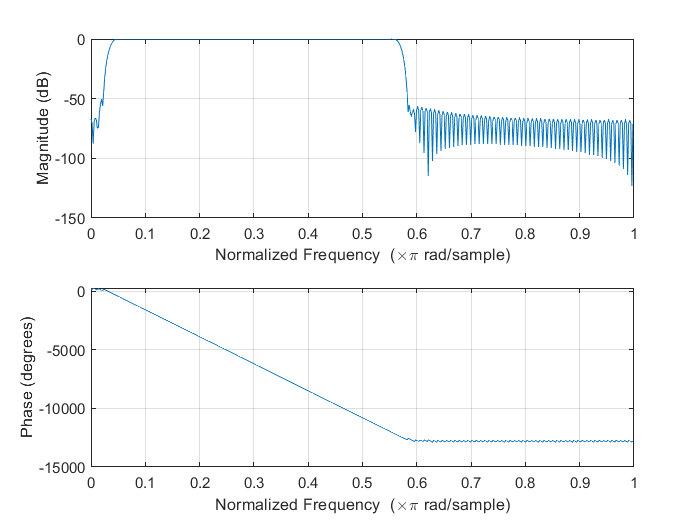

resultAudio = bandpassVocalFilter(samples, order,fsample, level);

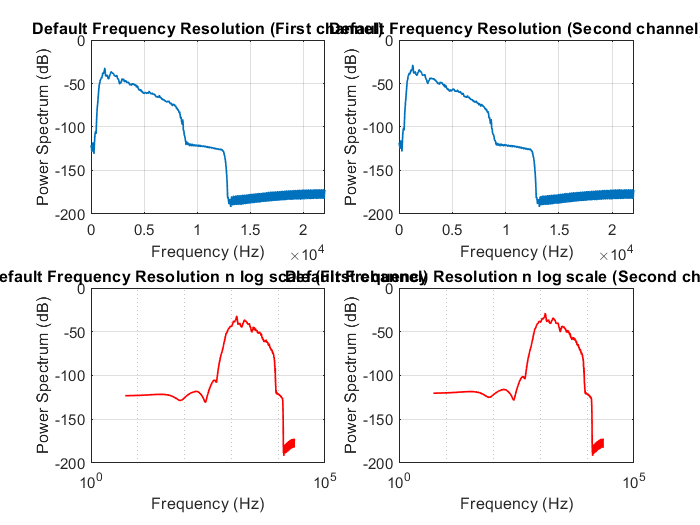


player = audioplayer(resultAudio, fsample);
play(player);

ShowPSD2(resultAudio, fsample);


% Wiener filter approach

resultAudio2 = wienerFilter(resultAudio, fsample, 0.40);

The shift length have to be an integer as it is the number of samples.
shift length is fixed to 440
The shift length have to be an integer as it is the number of samples.
shift length is fixed to 440


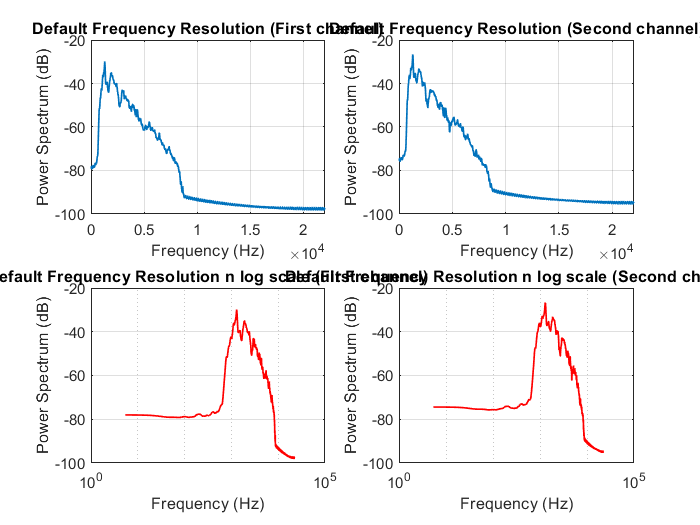


player = audioplayer(resultAudio2, fsample);
play(player);

ShowPSD2(resultAudio2, fsample);

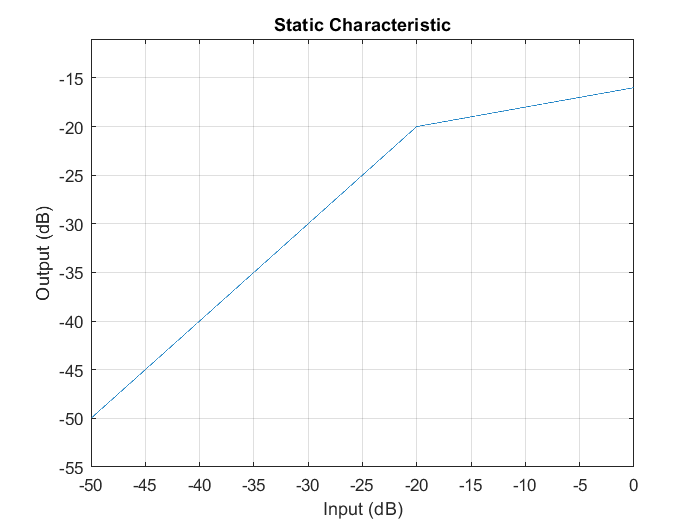

% Compressor 

dRC = compressor(-20,5,'SampleRate',fsample);
visualize(dRC)

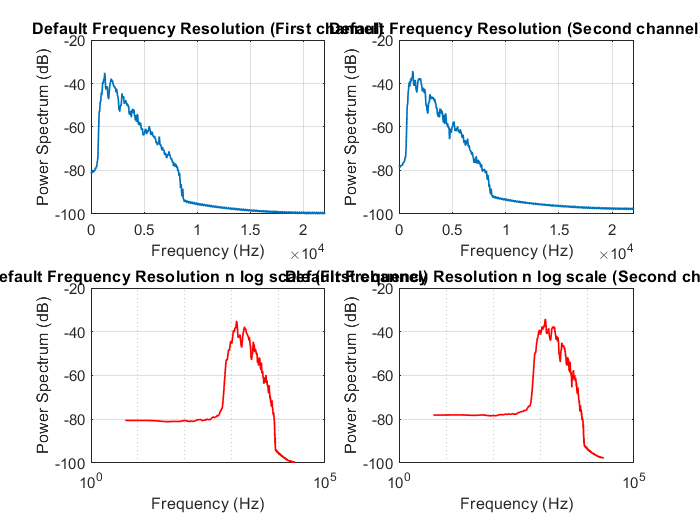


resultAudio3 = dRC(resultAudio2);

player = audioplayer(resultAudio3, fsample);
play(player);

ShowPSD2(resultAudio3, fsample);

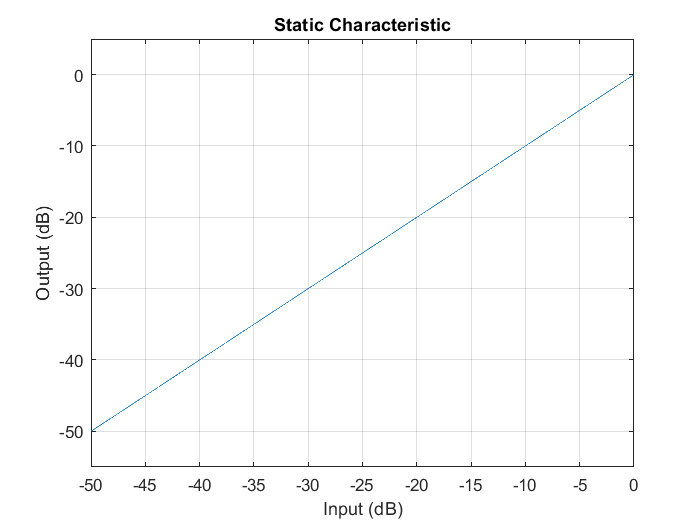

% Expender

dRC = expander(-80, 5, 'SampleRate',fsample);
visualize(dRC);

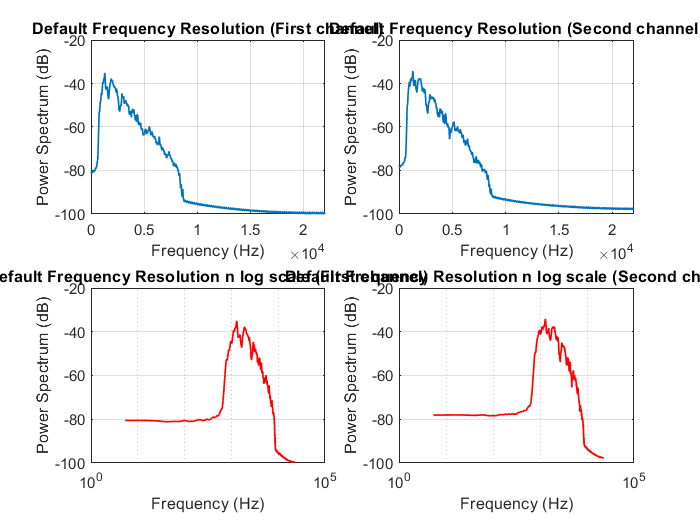


resultAudio4 = dRC(resultAudio3);


player = audioplayer(resultAudio4, fsample);
play(player);

ShowPSD2(resultAudio4, fsample);

audiowrite('enhancedTestAudio4.wav', resultAudio4, fsample)

